# **demo05 of Im2mesh package**

demo05 - Thresholds in polyline smoothing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Import Image

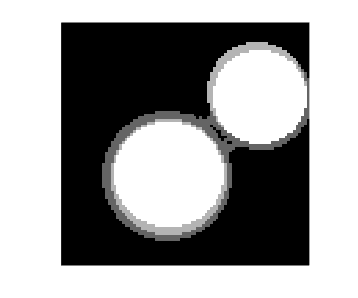

im = imread('Circle.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Zoom in

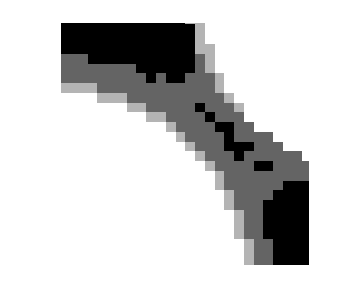

imshow( im,'InitialMagnification','fit' );
xlim([40.8 66.2])
ylim([29.3 54.2])

## When thresholds are zeros

opt = [];
% thresholds for polyline smoothing
opt.thresh_turn = 0;
opt.thresh_vert_smooth = 0;

opt.tolerance = 0.01;  % do not simplify polyline

[vert,tria,tnum] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                623               1078
         10                659               1630
         20                668               2520
         20                668               2520


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                868               1078
         10                868               1078
         20                893               7880
         26                894               8055


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

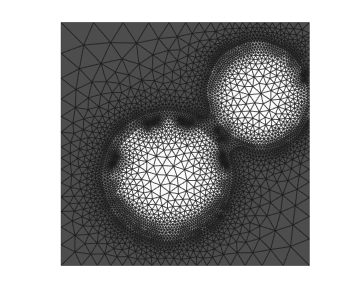

plotMeshes(vert,tria,tnum)

Zoom in

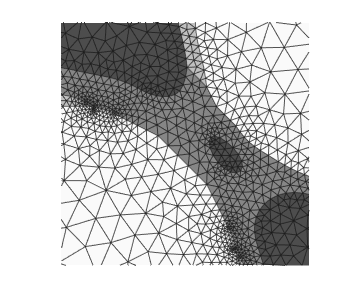

plotMeshes(vert,tria,tnum)
xlim([41.6 67.0])
ylim([36.2 61.1])

We saw some polygons were disappeared when compared to the input image. This disappearing issue is caused by polyline over-smoothing. 

We can set thresholds for polyline smoothing to avoid this issue.

## Set thresholds for polyline smoothing

opt = [];
% thresholds for polyline smoothing
opt.thresh_turn = 10;
opt.thresh_vert_smooth = 20;

opt.tolerance = 0.01;  % do not simplify polyline

[vert,tria,tnum] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                670               1170
         10                705               1601
         20                709               2335
         20                709               2335


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                886               1170
         10                886               1170
         20                922               7060
         23                924               7166


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

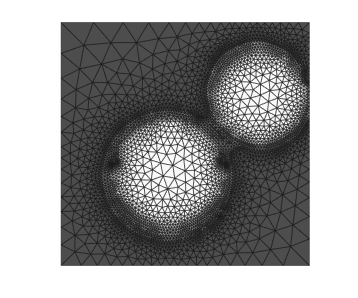

plotMeshes(vert,tria,tnum)

Zoom in

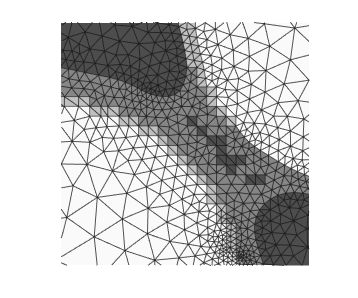

plotMeshes(vert,tria,tnum)
xlim([41.6 67.0])
ylim([36.2 61.1])

The new boundaries are better. 

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo